% Load the necessary data if not already in the workspace
load('trainingSet.mat'); % XTrain, YTrain
load('validationSet.mat'); % XTest, YTest


% Training a GBM Model for Multi-Class Classification without specifying GentleBoost
t = templateTree('MaxNumSplits', 20);
% Using fitcensemble with a decision tree learner and not explicitly specifying GentleBoost
gbmModel = fitcensemble(XTrain, YTrain, 'Learners', t, 'LearnRate', 0.1, 'NumLearningCycles', 100);

[YPred, scores] = predict(gbmModel, XTest);


% Convert YPred to categorical if YTest is categorical
YPred = categorical(YPred);

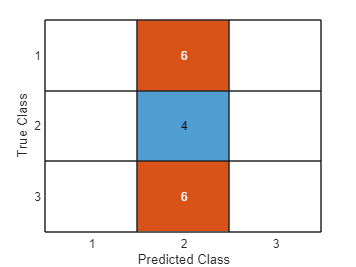

% Evaluate the classifier
confMat = confusionmat(YTest, YPred);
confusionchart(confMat);

accuracy = sum(YTest == YPred) / numel(YTest);
disp(['Accuracy: ', num2str(accuracy)]);

Accuracy: 0.25
